@Freq = 1000.000, SNR = 6.023 dB, SNDR = -18.074 dB, SFDR = 23.316 dB, HD2 = 23.316 and HD3 = 28.121


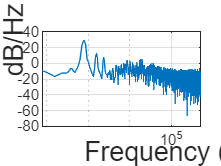

@Freq = 2000.000, SNR = 6.694 dB, SNDR = -31.516 dB, SFDR = 14.000 dB, HD2 = 14.000 and HD3 = 15.143


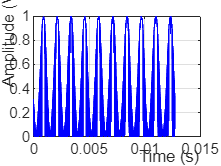

@Freq = 6200.000, SNR = 5.317 dB, SNDR = -36.185 dB, SFDR = 3.301 dB, HD2 = 3.301 and HD3 = 9.671


@Freq = 11400.000, SNR = 5.502 dB, SNDR = -39.277 dB, SFDR = 2.229 dB, HD2 = 2.229 and HD3 = 3.308


@Freq = 16600.000, SNR = 4.361 dB, SNDR = -33.588 dB, SFDR = 3.361 dB, HD2 = 8.558 and HD3 = 3.361


@Freq = 21800.000, SNR = -3.940 dB, SNDR = -28.443 dB, SFDR = 7.286 dB, HD2 = 19.701 and HD3 = 7.286


@Freq = 27100.000, SNR = 1.601 dB, SNDR = -47.768 dB, SFDR = -5.940 dB, HD2 = -5.940 and HD3 = 1.035


@Freq = 32300.000, SNR = -7.221 dB, SNDR = -32.581 dB, SFDR = 6.058 dB, HD2 = 6.058 and HD3 = 13.417


@Freq = 37500.000, SNR = 0.491 dB, SNDR = -40.037 dB, SFDR = -0.261 dB, HD2 = 0.760 and HD3 = -0.261


@Freq = 42700.000, SNR = -1.846 dB, SNDR = -32.219 dB, SFDR = 3.687 dB, HD2 = 3.687 and HD3 = 12.846


@Freq = 47900.000, SNR = -2.368 dB, SNDR = -35.237 dB, SFDR = 4.378 dB, HD2 = 4.378 and HD3 = 8.489


@Freq = 53100.000, SNR = -9.177 dB, SNDR = -33.219 dB, SFDR = 3.643 dB, HD2 = 3.643 and HD3 = 16.761


@Freq = 58300.000, SNR = -4.800 dB, SNDR = -43.582 dB, SFDR = -9.134 dB, HD2 = -9.134 and HD3 = 2.216


@Freq = 63500.000, SNR = -6.605 dB, SNDR = -35.866 dB, SFDR = 1.372 dB, HD2 = 7.119 and HD3 = 1.372


@Freq = 68700.000, SNR = -6.479 dB, SNDR = -30.165 dB, SFDR = 11.656 dB, HD2 = 11.656 and HD3 = 16.236


@Freq = 73900.000, SNR = -8.742 dB, SNDR = -44.763 dB, SFDR = -11.014 dB, HD2 = -0.049 and HD3 = -11.014


@Freq = 79200.000, SNR = -11.557 dB, SNDR = -34.597 dB, SFDR = 8.843 dB, HD2 = 8.843 and HD3 = 11.152


@Freq = 84400.000, SNR = -7.156 dB, SNDR = -51.452 dB, SFDR = -8.713 dB, HD2 = -8.713 and HD3 = -7.069


@Freq = 89600.000, SNR = -9.092 dB, SNDR = -32.301 dB, SFDR = 3.498 dB, HD2 = 9.822 and HD3 = 3.498


@Freq = 94800.000, SNR = -12.476 dB, SNDR = -41.877 dB, SFDR = -2.687 dB, HD2 = -2.687 and HD3 = 5.348


@Freq = 100000.000, SNR = -11.012 dB, SNDR = -44.047 dB, SFDR = -4.197 dB, HD2 = -4.197 and HD3 = -3.838


@Freq = 250000.000, SNR = -15.159 dB, SNDR = -30.955 dB, SFDR = 0.000 dB, HD2 = NaN and HD3 = 0.000


clearvars
freq_array = readtable('./ADC_Data/CML-Data/12-2-EthanTB-Board4_SEDE-Freq_1k_250k-SIN_1000mV-CLK_1MHz_Duty50%/freq_array.csv');
freq_array = table2array(freq_array);
%%% Remember to change this! if folder change
filepath = './ADC_Data/CML-Data/12-2-EthanTB-Board4_SEDE-Freq_1k_250k-SIN_1000mV-CLK_1MHz_Duty50%/';
% 1:freq, 2: SNR, 3: SNDR 4:SFDR
BigSet = zeros(length(freq_array),4);
% :length(freq_array)
for i = 1:length(freq_array)
    freq = num2str(freq_array(i));
    BigSet(i,1) = freq_array(i);
    filename = strcat(filepath,'SIN_',num2str(freq_array(i)),'.0Hz_.csv');
    data = readtable(filename);
    data_dec = table2array(data);
    % data_dec = data_dec(data_dec ~= 0);
    data_bin = dec2bin(data_dec);
    data_EOC = str2num(data_bin(:,1));
    data_Code = str2num(data_bin(:,2:10));
    data_NewCode = size(length(data_Code),1);
    data_Code_dec = bin2dec(num2str(data_Code));

    rising_edge_indices = find(diff(data_EOC) == 1)+1;
    time_diff = diff(rising_edge_indices);
    for k = 1:length(rising_edge_indices)
        index = rising_edge_indices(k);
        data_NewCode(k,1) = data_Code_dec(index);

    end
    data_NewDec = data_NewCode;
    % data_NewDec = floor(medfilt1(data_NewCode, 10));
    % data_NewDec = data_NewDec(1:5000);
    Fs=1e6;
    num_segments=1;
    f_signal = freq_array(i);
    f_s = Fs;
    BW =Fs/2;
    sample_size=2^floor(log2(length(data_NewDec)));
    % sample_size=length(data_NewDec);
    periodogram_length = sample_size / num_segments;
    fbin = f_s / periodogram_length;
    plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
        plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
        f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    set(gcf,'color','w')
    BigSet(i,2) = SNR;
    BigSet(i,3) = SNDR;
    BigSet(i,4) = SFDR;
    
    %%%%%% Reconstructed the waveform
    % Parameters
    fs = 1e6;                 % Sampling rate in Hz
    N = length(data_NewDec);                  % Number of samples
    bit_depth = 9;            % ADC bit resolution
    V_min = 0;              % Minimum input voltage
    V_max = 1;               % Maximum input voltage
    
    % Map codes to voltage
    voltages = ((data_NewDec / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;
    
    % Create time axis
    t = (0:N-1) / fs;
    
    % Plot the reconstructed waveform
    figure;
    plot(t, voltages, 'b');
    title('Reconstructed Time-Domain Waveform');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

save('BigSet.mat', 'BigSet');

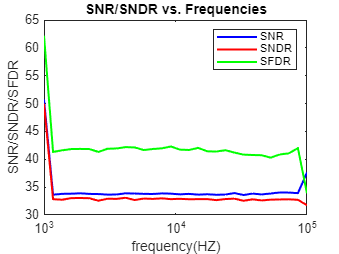

save('BigSet.mat', 'BigSet');
load('BigSet.mat')
figure
semilogx(BigSet(:,1), BigSet(:,2), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(BigSet(:,1), BigSet(:,3), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
semilogx(BigSet(:,1), BigSet(:,4), 'g-', 'LineWidth', 1.5, "DisplayName","SFDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR/SFDR");
title("SNR/SNDR vs. Frequencies");
legend;

clearvars
load('./ADC_Data/CML-Data/12-2-EthanTB-Board4_SEDE-Freq_1k_250k-SIN_1000mV-CLK_1MHz_Duty50%/zhihao_100k_42_24.mat')
binary = char(filteredData);
DEC = binary(:,2:10);
DEC_New = bin2dec(DEC);

% Fs=1e6;
% num_segments=1;
% f_signal = 100e3;
% f_s = Fs;
% BW =Fs/2;
% sample_size=2^floor(log2(length(DEC_New)));
% % sample_size=length(data_NewDec);
% periodogram_length = sample_size / num_segments;
% fbin = f_s / periodogram_length;
% plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
% [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
%     plot_periodogram_SFDR(DEC_New, periodogram_length, num_segments, f_signal, ...
%     f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
% fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
% set(gcf,'color','w')
% BigSet(i,2) = SNR;
% BigSet(i,3) = SNDR;
% BigSet(i,4) = SFDR;

fs = 1e6;                 % Sampling rate in Hz
N = length(DEC_New);                  % Number of samples
bit_depth = 9;            % ADC bit resolution
V_min = 0;              % Minimum input voltage
V_max = 1;               % Maximum input voltage

% Map codes to voltage
voltages = ((DEC_New / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;

% Create time axis
t = (0:N-1) / fs;

% Plot the reconstructed waveform
figure;
plot(t, voltages, 'b');
title('Reconstructed Time-Domain Waveform');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;